% 特定的
% 选手
m1=73;
Sw=0.5;

% 环境
% 不变
m0=6.8;
m=m1+m0;
g=9.8;
cr=0.004*5;     k.f = cr;   r1=cr;
cw=0.0397;      k.a = cw;   r2=cw;  % 空阻
% 可变
Mode=2;
switch Mode
    case 1
        % rho=1.293*(实际压力 / 标准物理大气压)*(273.15 / 实际绝对温度);
    case 2
        rho = 1.29; % biaokuang changwen 1.2 05;
end
C=cw;S_tb=Sw;
kk=1/2*C*rho*S_tb;
% 地图


L =     6.0000    6.0500   12.0000   12.0500   18.0000   18.0500   24.0000   24.0500   30.0000   30.5000   36.0000
         0         0    2.0000         0   -2.0000         0         0         0    2.0000         0   -2.0000
         0    1.0000         0    1.0000         0    1.0000         0    1.0000         0    1.0000         0
   60.0000   90.0000  120.0000  150.0000  180.0000  210.0000  240.0000  270.0000  300.0000  330.0000         0




% S0=43.3;% 世界锦标赛个人计时赛男子组
Mode.rider=2;
switch Mode.rider
    case 1
        treal=35*60+54+10/60;
        va=max(sx)/treal;
        va(2)=va*3.6;
        Ppred=440;  % polyval(p.z1,treal*1.1)
    case 2
        treal=30*60+13+49/60;
        va=max(L(1,:))/treal;
        va(2)=va*3.6;
        Ppred=367.5;  % polyval(p.z1,treal*1.1)

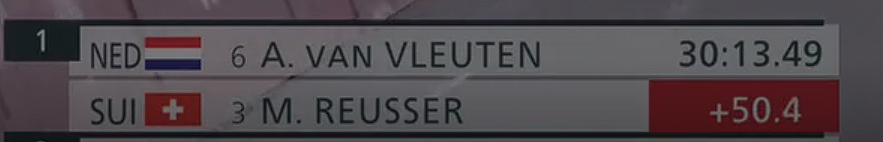

end

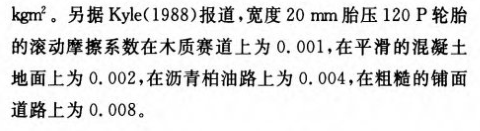

% time
% test
Mode.P = 0 ;
switch Mode.P
    case 0
        P0 = 0.4 * Ppred ;
        pm.P0 = {[0.20 0.95] 1.55 30 0.8};
    case 1 % 直接输入
        P0 = 73*4 ;  % W
    case 2
        P0 = polyval(p.z1,t1.c) ;
    case 3
        P0 = 0.7*polyval(p.z1,t1.c) ;
end


